# Regression of load data

## **Data input**

Regression method: multiple linear regression with least-square-error

### 1) Base parameters

Select industry segement

Branche = "Industry plant"; % "Industry plant" is the placeholder from the paper, user can create new segments as required (corresponding import data set must exist)

Select energy carrier

Sektor = "Strom"; % "Strom": electricity; "Waerme": heat

### 2) Regression mode

"Standard": only the combination of independent variables chosen for each industry segment in the code below will be used

"Alle Varianten": all combinations of independent variables will be used, this is particularly useful to find the best sets of independent variables for new industry segments

Modus = "Standard";

### 3) Enter metadata for two-stage regression

These values are only used to synthesize location load profiles as an intermediary step before the segment model regression takes place

Referenzjahr = 2018; % Reference year for intermediate synthetization
Wetterjahr = 1; % Weather year
Strommarktjahr = 2; % Electricity market year

`--- End of user inputs ---`

### Industry segment configuration

% Add paths for input data and functions
addpath(genpath('Functions_Data_Import'))
addpath(genpath('Functions_Data_Regression'))

load('Regression_weitereParameter.mat');

% State characteristics of each industry segment
% USER: add parameters for new industry segments
Berechnungsart = "Regression";
switch Sektor
    case "Strom"
        Varianten = Varianten_Strom;
        clear Varianten_Strom Varianten_Waerme
        switch Branche
            case "Industry plant"
                load('Importdaten_Strom_IndustryPlant.mat'); % Import results from import step
                Zeitreihen=Importdaten_Strom_IndustryPlant;
                clear Importdaten_Strom_IndustryPlant;
                Variante = "Lastgang~Tagtyp_1_7+Temperatur+Globale_Strahlung+Woche+DayAhead"; % Pre-defined set of independent variables for normal operation
                Variante_Betriebsruhe = "Lastgang~Tagtyp_1_3+Woche"; % Pre-defined set of independet variables for shutdown periods
                Variantenmodus = "Normalbetrieb";
                % Typical shutdown periods in industry segment
                Beginn = ["01.01.","24.12."];
                Ende   = ["01.01.","31.12."];
        end
    case "Waerme"
        Varianten = Varianten_Waerme;
        clear Varianten_Strom Varianten_Waerme
        % Laden des branchenspezifischen structs
        switch Branche
            case "Industry plant"
                load('Importdaten_Waerme_IndustryPlant.mat');
                Zeitreihen=Importdaten_Waerme_IndustryPlant;
                clear Importdaten_Waerme_IndustryPlant;
                Variante = "Lastgang~Tagtyp_1_7+Temperatur+Globale_Strahlung+Woche+DayAhead";
                Variante_Betriebsruhe = "Lastgang~Tagtyp_1_3+Woche";
                Variantenmodus = "Normalbetrieb";
                % typische Betriebsruhe
                Beginn = ["01.01.","24.12."];
                Ende   = ["01.01.","31.12."];
        end
end

### **Create location model for each location within current industry segment (1. stage of regression)**

% Add all data per location
Zeitreihen_Regression = Zusammenfuehrung_Zeitreihen(Zeitreihen);

switch Modus
    case "Standard" % Use only pre-defined set of independent variables
        switch Berechnungsart
            case "Regression"
                switch Variantenmodus
                    case "Normalbetrieb"
                        [Einzelmodelle] = Regression_Einzelmodelle_OLS(Zeitreihen_Regression,Variante);
                    case "Betriebsruhe"
                        [Einzelmodelle] = Regression_Einzelmodelle_OLS_v2(Zeitreihen_Regression,Variante,Variante_Betriebsruhe);
                end
            case "Synthese"
                [Einzelmodelle] = Synthese_Einzelmodelle(Zeitreihen_Regression);
        end
    case "alle Varianten"
        % Use all combinations of independent variables
        [Bewertung_Varianten,Bewertung_Varianten_Standorte,DayAhead_plausibel] = Regression_Einzelmodelle_Varianten_OLS(Zeitreihen_Regression,Varianten);
        return
end

### **Create industry segment model from location models for current industry segment (2. stage of regression)**

Step 1: Synthesize location models to uniform reference year using uniform reference weather and market data

Step 2: Use regression to determine industry segment model

% Import metadata

if exist('Feiertage_2000_bis_2050','var') == 0
    load('Feiertage_2000_bis_2050.mat');
end
if exist('Klimadaten_DE','var') == 0
    load('Klimadaten_DE.mat');
end
if exist('Strommarkt_DE','var') == 0
    load('Strommarkt_DE.mat');
end

% Assign day type and date index data
switch Sektor
    case "Strom"
        Vektor = ones(35040,1);
    case "Waerme"
        Vektor = ones(8760,1);
end
Zeitformat = Zeitzuordnung(Referenzjahr,"DE",Vektor,Feiertage_2000_bis_2050);

Time = Zeitformat.Time;
Tagtyp_1_7 = Zeitformat.Tagtyp_1_7_categorical;
Zeitindex_1_7 = Zeitformat.Zeitindex_1_7;
Tagtyp_1_5 = Zeitformat.Tagtyp_1_5_categorical;
Zeitindex_1_5 = Zeitformat.Zeitindex_1_5;
Tagtyp_1_3 = Zeitformat.Tagtyp_1_3_categorical;
Zeitindex_1_3 = Zeitformat.Zeitindex_1_3;
Tagtyp_1_1 = Zeitformat.Tagtyp_1_1_categorical;
Zeitindex_1_1 = Zeitformat.Zeitindex_1_1;
Monat = Zeitformat.Monat;
Woche = Zeitformat.Woche;
Tag = Zeitformat.Tag;

clear Vektor

% Assign shutdown periods
Betriebsruhe = ZuordnungBetriebsferien(Time,Beginn,Ende,Referenzjahr);

% Assign weather data
switch Sektor
    case "Strom"
        Temperatur = Klimadaten_DE(Wetterjahr).Zeitreihen_15min.Temperatur;
        Globale_Strahlung = Klimadaten_DE(Wetterjahr).Zeitreihen_15min.Globale_Strahlung;
        DayAhead = Strommarkt_DE(Strommarktjahr).DayAhead.DayAhead;
    case "Waerme"
        Temperatur = Klimadaten_DE(Wetterjahr).Zeitreihen_stuendlich.Temperatur;
        Globale_Strahlung = Klimadaten_DE(Wetterjahr).Zeitreihen_stuendlich.Globale_Strahlung;
end

% Create timetable with all relevant input data and independent variables
varNames = ["Temperatur","Globale_Strahlung","Betriebsruhe","Tagtyp_1_7","Zeitindex_1_7","Tagtyp_1_5","Zeitindex_1_5","Tagtyp_1_3","Zeitindex_1_3","Tagtyp_1_1","Zeitindex_1_1","Monat","Woche","Tag","DayAhead"];
Predictors = timetable(Time,Temperatur,Globale_Strahlung,Betriebsruhe,Tagtyp_1_7,Zeitindex_1_7,Tagtyp_1_5,Zeitindex_1_5,Tagtyp_1_3,Zeitindex_1_3,Tagtyp_1_1,Zeitindex_1_1,Monat,Woche,Tag,DayAhead,'VariableNames',varNames);

% Create industry segment model for current industry segment

switch Berechnungsart
    case "Regression"
        switch Variantenmodus
            case "Normalbetrieb"
                [Branchenmodell,Referenzzeitreihen] = Regression_Branchenmodelle_OLS(Einzelmodelle,Predictors,Variante);
            case "Betriebsruhe"
                [Branchenmodell,Referenzzeitreihen] = Regression_Branchenmodelle_OLS_v2(Einzelmodelle,Predictors,Variante,Variante_Betriebsruhe);
        end
        Branchenmodell_anonymisiert = Anonymisierung_Branchenmodell(Branchenmodell);
    case "Synthese"
        [Branchenmodell,Branchenmodell_anonymisiert,Referenzzeitreihen] = Synthese_Branchenmodell(Einzelmodelle,Feiertage_2000_bis_2050,Klimadaten_DE,Predictors)
end


### **Visualize location and segment model for visual inspection**

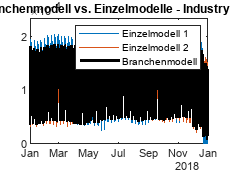

set(gcf,'Visible','on')
switch Variantenmodus
    case "Normalbetrieb"
        Branchen_vs_Einzel(Branchenmodell,Referenzzeitreihen,Branche);
    case "Betriebsruhe"
        Branchen_vs_Einzel_v2(Branchenmodell,Referenzzeitreihen,Branche);
end

### **Calculate statistical parameters**

Calculate $R^2$, $R_{\textrm{korr}\ldotp }^2$,$\textrm{MAPE}$ and $\textrm{nRMSE}$

Kennzahlen_Rohdaten_vs_Einzelmodelle = 4×5 table
    Standort    OrdinaryRsquared    AdjustedRsquared      MAPE       nRMSE  
    ________    ________________    ________________    ________    ________

    "1"             0.95609             0.95516          0.07731    0.054124
    "2"             0.97456             0.97402         0.041959    0.042124
    "mean"          0.96532             0.96459         0.059635    0.048124
    "median"        0.96532             0.96459         0.059635    0.048124


Zeitreihen_Rohdaten_vs_Einzelmodelle = 1×2 struct array with fields:
    Standort
    Zeitreihe_Vergleich


Kennzahlen_Rohdaten_vs_Branchenmodell = 4×5 table
    Standort    OrdinaryRsquared    AdjustedRsquared      MAPE       nRMSE  
    ________    ________________    ________________    ________    ________

    "1"             0.91623             0.91446          0.14039    0.076257
    "2"             0.92327             0.92165         0.093914    0.075659
    "mean"          0.91975             0.91805          0.11715    0.075958
    "median"        0.91975             0.91805          0.11715    0.075958


Zeitreihen_Rohdaten_vs_Branchenmodell = 1×2 struct array with fields:
    Standort
    Zeitreihe_Vergleich


Kennzahlen_Einzelmodelle_vs_Branchenmodell = 4×5 table
    Standort    OrdinaryRsquared    AdjustedRsquared      MAPE       nRMSE  
    ________    ________________    ________________    ________    ________

    "1"             0.95811             0.95722           10.317    0.047933
    "2"             0.94737             0.94626         0.094197    0.061659
    "mean"          0.95274             0.95174           5.2055    0.054796
    "median"        0.95274             0.95174           5.2055    0.054796


Zeitreihen_Einzelmodelle_vs_Branchenmodell = 1×2 struct array with fields:
    Standort
    Zeitreihe_Vergleich


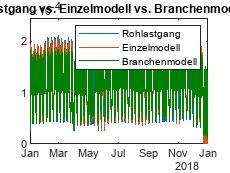

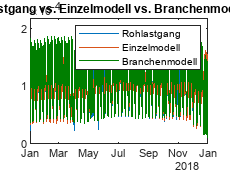

Zeitreihen_Vergleich = 1×2 struct array with fields:
    Standort
    Zeitreihen_Vergleich


switch Berechnungsart
    case "Regression"
        % Input data vs. location models
        % CAUTION: Confidential data!
        [Kennzahlen_Rohdaten_vs_Einzelmodelle,Zeitreihen_Rohdaten_vs_Einzelmodelle] = Berechnung_Statistik_Regression(Zeitreihen_Regression,Einzelmodelle,Variantenmodus,Time,"Rohlastgang","Einzelmodell",Sektor)

        % Input data vs. segment model
        % Caution: Confidential data!
        [Kennzahlen_Rohdaten_vs_Branchenmodell,Zeitreihen_Rohdaten_vs_Branchenmodell] = Berechnung_Statistik_Regression(Zeitreihen_Regression,Branchenmodell,Variantenmodus,Time,"Rohlastgang","Branchenmodell",Sektor)

        % Location models vs. segment mode
        % Caution: Possibly confidential data!
        [Kennzahlen_Einzelmodelle_vs_Branchenmodell,Zeitreihen_Einzelmodelle_vs_Branchenmodell] = Berechnung_Statistik_Regression(Referenzzeitreihen,Branchenmodell,Variantenmodus,Time,"Einzelmodelle","Branchenmodell",Sektor)

        Zeitreihen_Vergleich = Vergleich_Zeitreihen(Zeitreihen_Rohdaten_vs_Einzelmodelle,Zeitreihen_Rohdaten_vs_Branchenmodell)
        clear Zeitreihen_Rohdaten_vs_Einzelmodelle Zeitreihen_Rohdaten_vs_Branchenmodell Zeitreihen_Einzelmodelle_vs_Branchenmodell 
end

Calculate $R^2$,$\textrm{MAPE}$ and $\textrm{nRMSE}$ f�r for synthesized data (heat):

switch Berechnungsart
    case "Synthese"
        % Input data vs. location models
        % CAUTION: Confidential data!
        [Kennzahlen_Rohdaten_vs_Einzelmodelle,Zeitreihen_Rohdaten_vs_Einzelmodelle] = Berechnung_Statistik_Synthese(Zeitreihen_Regression,Einzelmodelle,Time,"Rohlastgang","Einzelmodell")

        % Input data vs. segment model
        % Caution: Confidential data!
        [Kennzahlen_Rohdaten_vs_Branchenmodell,Zeitreihen_Rohdaten_vs_Branchenmodell] = Berechnung_Statistik_Synthese(Zeitreihen_Regression,Branchenmodell,Time,"Rohlastgang","Branchenmodell")

        % Location models vs. segment mode
        % Caution: Possibly confidential data!
        [Kennzahlen_Einzelmodelle_vs_Branchenmodell,Zeitreihen_Einzelmodelle_vs_Branchenmodell] = Berechnung_Statistik_Synthese(Referenzzeitreihen,Branchenmodell,Time,"Einzelmodelle","Branchenmodell")

        Zeitreihen_Vergleich = Vergleich_Zeitreihen(Zeitreihen_Rohdaten_vs_Einzelmodelle,Zeitreihen_Rohdaten_vs_Branchenmodell)
        clear Zeitreihen_Rohdaten_vs_Einzelmodelle Zeitreihen_Rohdaten_vs_Branchenmodell Zeitreihen_Einzelmodelle_vs_Branchenmodell 
end

Referenzzeitreihen_Einzelmodelle = Referenzzeitreihen;
Referenzzeitreihe_Branchenmodell = Branchenmodell.Referenzzeitreihen;
Branchenmodell = rmfield(Branchenmodell,'Referenzzeitreihen');
clear Referenzzeitreihen

### **Create structured data to save**

% USER: Caution - user must ensure that no confidential data is shared. See example for distinction between "safe" and "unsafe" data.
% USER: Must manually save the resulting structs from workspace

switch Sektor
    case "Strom"
        switch Branche
            case "Industry plant"
                Industry_plant_Branchenmodell_Strom = Branchenmodell_anonymisiert; % Safe (only reduced segment model as linear model for synthesis)
                Industry_plant_Branchenmodell_Strom_nicht_anonymisiert = Branchenmodell; % Unsafe (full compact linear model of segment model)
                Industry_plant_Strom_Einzelmodelle = Einzelmodelle; % Unsafe (location models as compact linear models)
        end
    case "Waerme"
        switch Branche
            case "Industry plant"
                Industry_plant_Brahnchemodell_Waerme = Branchenmodell_anonymisiert; % Safe (only reduced segment model as linear model for synthesis)
                Industry_plant_Branchenmodell_Waerme_nicht_anonymisiert = Branchenmodell; % Unsafe (full compact linear model of segment model)
                Industry_plant_Waerme_Einzelmodelle = Einzelmodelle; % Unsafe (location models as compact linear models)
        end
end

clear Beginn Ende Betriebsruhe Branchenmodell Einzelmodelle
clear Globale_Strahlung Temperatur Monat Woche Tag Predictors Tagtyp_1_1 Tagtyp_1_3 Tagtyp_1_5 Tagtyp_1_7
clear Zeitformat Wetterjahr Sektor Modus Referenzjahr Zeitreihe_Art Branche
clear Time varNames Varianten_Strom Varianten_Waerme Varianten
clear Zeitindex_1_1 Zeitindex_1_3 Zeitindex_1_5 Zeitindex_1_7 %Zeitreihen %Zeitreihen_Regression